# Augmented Reality Matlab Capstone Project

## Access All Relevant File Paths

%--- Add paths to files---
addpath("All Functions/Control Functions/")
addpath("All Functions/CORF Functions/")
addpath("All Functions/doors/")
addpath("All Functions/windows/")
addpath("All Functions/LSD Rafael Matlab/")
addpath("All Functions/Functions For Augmenting Workflow")
addpath("Pictures/")

## Load Video Frame or Reference Picture

image_path = "sample_floor_plan27.jpeg"

image_path = "sample_floor_plan27.jpeg"

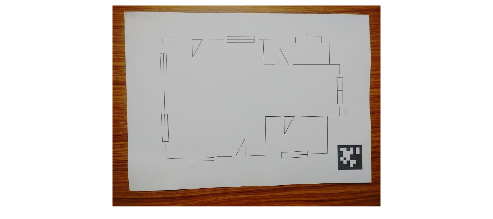

img = imread(image_path);
if isempty(img)
    error("Image not found or unreadable.");
end
imshow(img);

## Get Camera Intrinsics

data = load('calibrationSession.mat');
intrinsics = cameraParams.Intrinsics;

## Estimate Pose

tagSize = 31; % in mm
tagFamily = "tag36h11";
[~, ~, tagPose] = readAprilTag(img, tagFamily, intrinsics, tagSize);

## Display the Axis

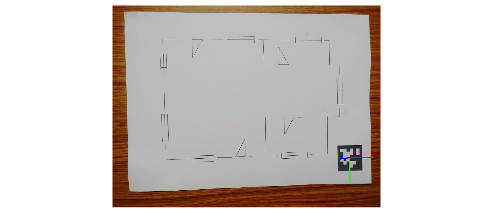

annotatedImage = helperInsertXYZAxes(img, tagPose, intrinsics, tagSize);
figure
imshow(annotatedImage)

## Rotate The Axis

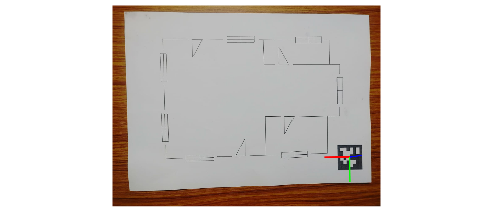

rotationAngles = [0 180 0];
tform = rigidtform3d(rotationAngles, [0 0 0]);
updatedR = tagPose.R * tform.R;
tagPose = rigidtform3d(updatedR, tagPose.Translation);


annotatedImage = helperInsertXYZAxes(img, tagPose, intrinsics, tagSize);
figure
imshow(annotatedImage)

## Document Detection Part 1

%--- This work flow aims to remove the surrounding background ---%
% --- Step1: Mask Out April Tag ---%
[cubeWidth, cubeHeight, cubeDepth] = deal(tagSize);

vertices = [ cubeWidth/2 -cubeHeight/2 0; 
             cubeWidth/2  cubeHeight/2 0;
            -cubeWidth/2  cubeHeight/2 0;
            -cubeWidth/2 -cubeHeight/2 0]; % World coordinates of april tag

projectedVertices = world2img(vertices, tagPose, intrinsics); % Image coordinates of april tagminX = min(projectedVertices(:,1));

minX = min(projectedVertices(:,1));
maxX = max(projectedVertices(:,1));
minY = min(projectedVertices(:,2));
maxY = max(projectedVertices(:,2));

bbox = [minX, minY, maxX-minX, maxY-minY];  % [x, y, width, height]

maskedImage = img;  % Initialize maskedImage with the original
% Scale bbox by 10 percent
scale = 0.1;
scaled_bbox = bboxScaler(bbox, scale)

scaled_bbox = 1.0e+03 *

    1.0676    0.6595    0.1320    0.1323


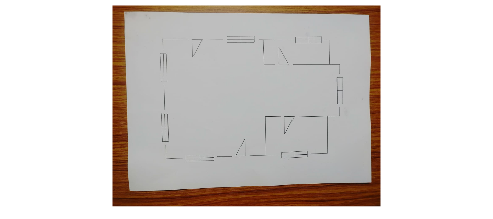

% Begin masking the april tag
box = round(scaled_bbox);  % [x y w h]
x1 = max(1, box(1));
y1 = max(1, box(2));
x2 = min(size(img,2), x1 + box(3) - 1);
y2 = min(size(img,1), y1 + box(4) - 1);

% Create mask for region
mask = false(size(img,1), size(img,2));
mask(y1:y2, x1:x2) = true;

% Region fill (works on grayscale or per channel)
if size(img, 3) == 3
     for c = 1:3
         channel = uint8(maskedImage(:,:,c));
         filled = regionfill(channel, mask);
         maskedImage(:,:,c) = filled;
     end
else
    maskedImage = regionfill(maskedImage, mask);
end
imshow(maskedImage)

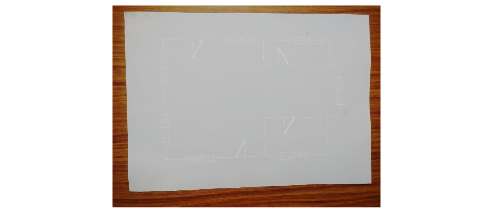



%--- Step 2: Erase all contents of the paper via Erosion and Dilation ---%
% Define a 5x5 square structuring element
se = strel('square', 5);

% Apply closing operation 3 times
J = maskedImage;
for k = 1:3
    J = imclose(J, se);
end
imshow(J)


%--- Step 3: Run Square Detection Fxn to get bbox of  A4 paper ---%
% --- Convert to grayscale ---
if ndims(J) == 3
    gray = rgb2gray(J);
else
    gray = J;
end

gray = im2double(gray);

% --- smoothing ---
gray = imgaussfilt(gray, 1.0);   % sigma ≈ 1 for mild smoothing

% --- Apply CORF contour detector ---
sigma = 2.5;     % CORF scale 
t = 0.3;         % hysteresis high threshold 

[corfResponse, bin] = CORF(gray, sigma, t); % bin is a binary contour image
squares = {};
bboxes  = [];
% Fill the thick-lined square to make it solid
bin_filled = imfill(bin, 'holes');

% Clean up with morphological closing
bin_filled = imclose(bin_filled, strel('disk', 3));

% get boundaries - 1 boundary per shape
[B, L] = bwboundaries(bin_filled, 'noholes');
% --- Detect Squares --- %
% Detect squares
squares = detectDocument(B, size(J));

fprintf('Number of squares detected: %d\n', length(squares));

Number of squares detected: 1


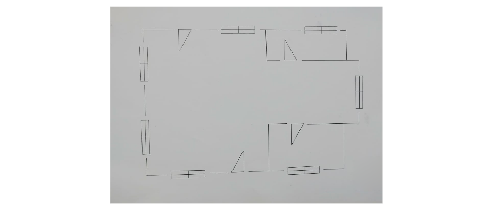

% --- Extract bounding boxes for detected squares ---
A4Paper = extractSquareBoundingBoxes(squares);

if isempty(A4Paper)
    % Give a default value if detection of A4 paper fails
    A4Paper = [60 49 1462 1032];
end
paper_standard = 1463504; % Typical area of an A4 paper
%Filter detected squares based on area to identify A4 paper 
% Increase tolerance if no squares are valid
validSquares = A4Paper(A4Paper(:,3).*A4Paper(:,4) > paper_standard * 0.5 & A4Paper(:,3).*A4Paper(:,4) < paper_standard * 1.6, :);

%--- Step 4: Crop the Original Image Without April Tag 'maskedImage' ---%
% Assuming validSquares is not empty, crop the original image based on the largest valid square
scale = -0.1; 
if ~isempty(validSquares)
    % Get the smallest valid square
    [~, idx] = min(validSquares(:, 3) .* validSquares(:, 4));
    cropBox = validSquares(idx, 1:4); % [x, y, width, height]
    % Scale crop box
    x = max(cropBox(1,1) - scale * cropBox(1,3) / 2, 0);
    y = max(cropBox(1,2) - scale * cropBox(1,4) / 2, 0);
    w = cropBox(1,3) * (1 + scale);
    h = cropBox(1,4) * (1 + scale);
    cropBox = [x, y, w, h];

    
    % Crop the image
    NoBackgroundImage = imcrop(maskedImage, cropBox);
    figure;
    imshow(NoBackgroundImage);
end

## Contour Detection Using CORF (1st Time Used on Floor Plan Proper)

% --- Convert to grayscale ---

if ndims(NoBackgroundImage) == 3
    gray = rgb2gray(NoBackgroundImage);
else
    gray = NoBackgroundImage;
end

gray = im2double(gray);

% --- smoothing ---
gray = imgaussfilt(gray, 1.0);   % sigma ≈ 1 for mild smoothing

% --- Apply CORF contour detector ---

[img_height, img_width] = size(gray);
img_diagonal = sqrt(img_height^2 + img_width^2);

% Scale sigma based on image size
% For close-up: sigma = 2.5 works
% For full page: sigma should be proportionally smaller
base_diagonal = 1000;  % Adjust based on your close-up image size
sigma = 2.5 * (base_diagonal / img_diagonal);
sigma = max(1.0, min(sigma, 3.0));  % Clamp between 1.0 and 3.0

t = 0.3;  

[corfResponse, bin] = CORF(gray, sigma, t); % bin is a binary contour image
bin_filled = imfill(bin, 'holes');
bin_filled = imclose(bin_filled, strel('disk', 3));
[B, L] = bwboundaries(bin_filled, 'noholes');


## Rectangle Detection

% --- Detect Rectangles --- %
% Detect Rectangles
rectangles = detectSquares(B, size(NoBackgroundImage));

fprintf('Number of rectangles detected: %d\n', length(rectangles));

Number of rectangles detected: 7



% --- Extract bounding boxes for detected squares and blur out all windows in floor plan ---
scale = 0.21; % Scales Window boxes by so that the window marker can be blurred out completely
% scale variable can be adjusted according to the perceived need
[ImgWthNoWindows, WindowBboxes] = blurOutRectangles(NoBackgroundImage, rectangles, scale);

Processing 7 rectangles/squares...
Rectangle 1: original bbox = [113.0, 155.0, 34.0, 136.0]
           scaled bbox = [109.8, 142.1, 40.5, 161.8]
Rectangle 2: original bbox = [119.0, 443.0, 35.0, 133.0]
           scaled bbox = [115.7, 430.4, 41.6, 158.3]
Rectangle 3: original bbox = [236.0, 637.0, 135.0, 34.0]
           scaled bbox = [223.2, 633.8, 160.7, 40.5]
Rectangle 4: original bbox = [432.0, 71.0, 134.0, 33.0]
           scaled bbox = [419.3, 67.9, 159.5, 39.3]
Rectangle 5: original bbox = [692.0, 620.0, 127.0, 36.0]
           scaled bbox = [679.9, 616.6, 151.1, 42.8]
Rectangle 6: original bbox = [759.0, 74.0, 129.0, 32.0]
           scaled bbox = [746.7, 71.0, 153.5, 38.1]
Rectangle 7: original bbox = [958.0, 269.0, 30.0, 128.0]
           scaled bbox = [955.1, 256.8, 35.7, 152.3]
Filling region 1: [142:303, 110:149]
Filling region 2: [430:587, 116:157]
Filling region 3: [634:673, 223:383]
Filling region 4: [68:106, 419:577]
Filling region 5: [617:659, 680:830]
Filling region 

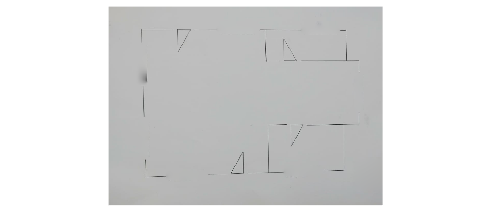

imshow(ImgWthNoWindows);

## Contour Detection Using CORF (3rd Time)

% --- Convert to grayscale ---
gray = ImgWthNoWindows;

gray = im2double(gray);

% --- Optional smoothing ---
gray = imgaussfilt(gray, 1.0);   % sigma ≈ 1 for mild smoothing

% --- Apply CORF contour detector ---
[img_height, img_width] = size(gray);
img_diagonal = sqrt(img_height^2 + img_width^2);

% Scale sigma based on image size
% For close-up: sigma = 2.5 works
% For full page: sigma should be proportionally smaller
base_diagonal = 1000;  % Adjust based on your close-up image size
sigma = 2.5 * (base_diagonal / img_diagonal);
sigma = max(1.0, min(sigma, 3.0));  % Clamp between 1.0 and 3.0

t = 0.3;  

[corfResponse, bin] = CORF(gray, sigma, t); % bin is a binary contour image
bin_filled = imfill(bin, 'holes');
bin_filled = imclose(bin_filled, strel('disk', 5));
[B, L] = bwboundaries(bin_filled, 'noholes');

## Triangle Detection

% Detect triangles
triangles = detectTriangles(B, size(ImgWthNoWindows));
% Enclose traingle in bounding box
scale = 0.19;
[ImgWthOnlyLines, DoorBboxes] = blurOutTriangles(ImgWthNoWindows, triangles, scale);

Filling region 1: [81:179, 260:322]
Filling region 2: [554:651, 468:527]
Filling region 3: [117:212, 673:733]
Filling region 4: [449:546, 701:760]
Filling region 5: [78:219, 916:971]


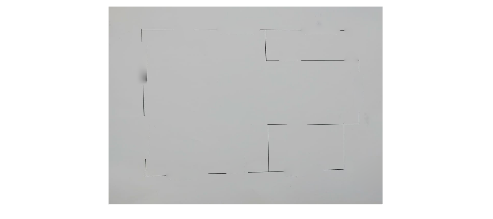

imshow(ImgWthOnlyLines);

## Line Segment Detection

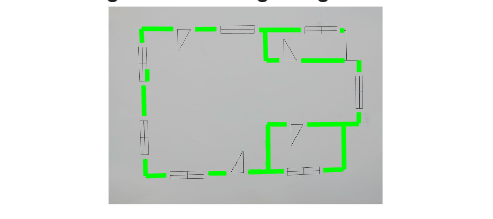

ImgWthOnlyLinesGray = rgb2gray(ImgWthOnlyLines);
%--- Run LSD Algorithm by Rafael ---
% LSD function can be tuned to improve performance ie increase no of line
% segments
[line_segments, ~, ~] = lsd(ImgWthOnlyLinesGray, 'scale', 1.0, 'ang_th', 22.5, 'log_eps', 3.0, 'density_th', 0.85);
%[line_segments, ~, ~] = lsd(ImgWthOnlyLinesGray,'scale', 1.0, 'quant', 1.0,'ang_th', 30, 'log_eps', -1.0, 'density_th', 0.5);
 
% Extract line segment coordinates
line_coordinates = line_segments(:, 1:4);

% An average of 25 000 - 30 000 line segments are always detected so
% merging would take some time compuationally
min_distance = 10;
min_angle = 5;
WallLines = merge_groups(line_coordinates, min_distance, min_angle);
size(WallLines);

figure
imshow(NoBackgroundImage);
hold on;
title('Merged Lines using HoughBundler');
for i = 1:size(WallLines,1)
    x = [WallLines(i,1) WallLines(i,3)];
    y = [WallLines(i,2) WallLines(i,4)];
    plot(x, y, 'g-', 'LineWidth', 2);
end
hold off;

## Window Feature Extraction

OriginalImg = NoBackgroundImage;
gap_max = 50.0;  % Maximum allowable distance to be considered a neighbor

window_marker = [];
all_window_lines = [];

% Scale all window boxes by 10 %
scalew = 0.1;
scaled_windowBoxes = bboxScaler(WindowBboxes, scalew);
WindowBboxes = scaled_windowBoxes;

for i = 1:size(WindowBboxes, 1) % Loop over all window boxes
    bbox = WindowBboxes(i,:);
    cropped_img = cropImage(OriginalImg, bbox, scalew);
    [pot_window_lines] = detectAndFilterLines(cropped_img, bbox, scalew);
    window_lines = filterSixWindowLines(pot_window_lines);
    %all_window_lines = [all_window_lines;window_lines;[0 0 0 0]]; % for
    marker = WindowPlacementMarker7(window_lines, WallLines);
    % Store the window marker and filtered lines for further processing
    window_marker = [window_marker; marker];

end

## Visualize Window Placement positions

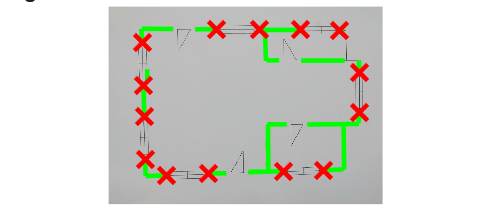

% --- Display Result ---
imshow(OriginalImg);
hold on;
title('Merged Lines with Door Lines Filtered and Markers');
for i = 1:size(WallLines, 1)
    x = [WallLines(i,1) WallLines(i,3)];
    y = [WallLines(i,2) WallLines(i,4)];
    plot(x, y, 'g-', 'LineWidth', 2);
end
for i = 1:size(window_marker, 1)
    if window_marker(i,1) ~= 0 && window_marker(i,2) ~= 0
        plot(window_marker(i,1), window_marker(i,2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    end
    if window_marker(i,3) ~= 0 && window_marker(i,4) ~= 0
        plot(window_marker(i,3), window_marker(i,4), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    end
end
hold off

## Door Feauture Extraction

door_markers = [];
all_door_lines = [];
all_door_lines1 = [];
scale = 0.1;
scaled_doorBoxes = bboxScaler(DoorBboxes, scale);
DoorBboxes = scaled_doorBoxes;

for i = 1:size(DoorBboxes, 1)
    bbox = DoorBboxes(i, :);
    cropped_img = cropImage(OriginalImg, bbox, scale);
    pot_door_lines = detectAndFilterLines(cropped_img, bbox, scalew);
    door_lines = filterTriangleLines(pot_door_lines);
    %all_door_lines = [all_door_lines; door_lines; [0 0 0 0]];
    
    if ~isempty(door_lines)
        lineLengths = sqrt((door_lines(:,3) - door_lines(:,1)).^2 + (door_lines(:,4) - door_lines(:,2)).^2);
        [~, minIndex] = min(lineLengths);
        shortestLine = door_lines(minIndex, :);
        marker = doorPlacementMarker(shortestLine, WallLines, 10.0, 50.0);
        if any(marker)
            door_markers = [door_markers; marker];
        end
    end
end

## Visualize Door Placement Positions

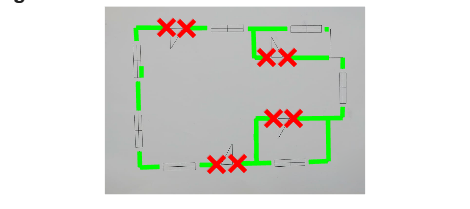

% --- Display Result ---
imshow(OriginalImg);
hold on;
title('Merged Lines with Door Lines Filtered and Markers');
for i = 1:size(WallLines, 1)
    x = [WallLines(i,1) WallLines(i,3)];
    y = [WallLines(i,2) WallLines(i,4)];
    plot(x, y, 'g-', 'LineWidth', 2);
end
for i = 1:size(door_markers, 1)
    if door_markers(i,1) ~= 0 && door_markers(i,2) ~= 0
        plot(door_markers(i,1), door_markers(i,2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    end
    if door_markers(i,3) ~= 0 && door_markers(i,4) ~= 0
        plot(door_markers(i,3), door_markers(i,4), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    end
end
hold off

## Translate All Results From Cropped Image Coordinates To Actual Image Coordinates

% ---Step 1: List Out Items To Translate ---
% - door_markers: Precise door placement coordinates
% - WallLines: wall lines
% - window_marker: Precise window placement coordinates

% ---Step 2: Commence Translation using cropBox---
wall_lines_orig = translateCropCoorToOriginal(WallLines, cropBox);
door_markers_orig = translateCropCoorToOriginal(door_markers, cropBox);
window_markers_orig = translateCropCoorToOriginal(window_marker, cropBox);


## Virtual 3D Visual of Building

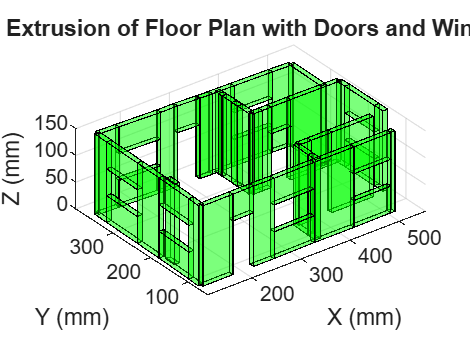

% --- Parameters ---
wallHeight = 150;        % mm
wallThickness = 10;      % mm
scaleFactor = 0.5;      % mm per pixel (adjust as needed)
% Heights for doors/windows
doorBase = (2/3)*wallHeight;
doorTop = wallHeight;
windowLowerHeight = (1/3)*wallHeight;
windowUpperBase = (2/3)*wallHeight;

% --- Scaled coordinates ---
scaleLines = @(L) L * scaleFactor;
lines = scaleLines(wall_lines_orig);
doors = scaleLines(door_markers_orig);
windows = scaleLines(window_markers_orig);

% --- Initialize storage ---
allVertices = [];
allFaces = [];
faceOffset = 0;

% --- Extrude Walls Fully ---
for i = 1:size(lines, 1)
    line = lines(i, :);
    vertices = createCuboidFromLine(line, wallHeight, wallThickness);

    % Add vertices and faces
    allVertices = [allVertices; vertices];
    faces = [1 2 3 4; 5 6 7 8; 1 5 6 2; 2 6 7 3; 3 7 8 4; 4 8 5 1] + faceOffset;
    allFaces = [allFaces; faces];
    faceOffset = faceOffset + 8;
end

% --- Doors: Upper 1/3 wall ---
for i = 1:size(doors, 1)
    door = doors(i, :);
    vertices = createCuboidFromLineAtHeight(door, doorBase, wallHeight - doorBase, wallThickness);

    allVertices = [allVertices; vertices];
    faces = [1 2 3 4; 5 6 7 8; 1 5 6 2; 2 6 7 3; 3 7 8 4; 4 8 5 1] + faceOffset;
    allFaces = [allFaces; faces];
    faceOffset = faceOffset + 8;
end

% --- Windows: Lower 1/3 ---
for i = 1:size(windows, 1)
    window = windows(i, :);
    vertices = createCuboidFromLineAtHeight(window, 0, windowLowerHeight, wallThickness);

    allVertices = [allVertices; vertices];
    faces = [1 2 3 4; 5 6 7 8; 1 5 6 2; 2 6 7 3; 3 7 8 4; 4 8 5 1] + faceOffset;
    allFaces = [allFaces; faces];
    faceOffset = faceOffset + 8;
end

% --- Windows: Upper 1/3 ---
for i = 1:size(windows, 1)
    window = windows(i, :);
    vertices = createCuboidFromLineAtHeight(window, windowUpperBase, windowLowerHeight, wallThickness);

    allVertices = [allVertices; vertices];
    faces = [1 2 3 4; 5 6 7 8; 1 5 6 2; 2 6 7 3; 3 7 8 4; 4 8 5 1] + faceOffset;
    allFaces = [allFaces; faces];
    faceOffset = faceOffset + 8;
end

% --- Visualization ---
figure;
patch('Vertices', allVertices, 'Faces', allFaces, ...
      'FaceColor', 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'k');
axis equal;
xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('Z (mm)');
title('3D Extrusion of Floor Plan with Doors and Windows');
view(3); grid on;

## Convert 2D Pixel Coordinates To Real World Coordinates

camExtrinsics = tagPose;
%--- Step 1: Convert wall lines from image Coordinates To World ----
% Initialize wall_lines_world
numLines = size(wall_lines_orig, 1);
wall_lines_world = zeros(numLines, 4);

% Loop over each wall line
for i = 1:numLines
    % Extract current line's endpoints as a 2x2 matrix
    line_2d = [wall_lines_orig(i,1:2); wall_lines_orig(i,3:4)];  % [x1 y1; x2 y2]
    
    % Initialize lines variable for this pair
    lines = zeros(2, 2);
    
    for j = 1:2
        imagePoint = line_2d(j, :);  % 1x2 point [x y]
        
        % Convert image point to world coordinates
        lines(j, :) = img2world2d(imagePoint, camExtrinsics, intrinsics);
    end
    
    % Flatten [x1 y1; x2 y2] -> [x1 y1 x2 y2]
    wall_lines_world(i, :) = reshape(lines.', 1, []);  % Transpose + reshape
end

%--- Step 2: Convert door marker positions from image to world
%coordinates ---

numLines = size(door_markers_orig, 1);
door_markers_world = zeros(numLines, 4);

% Loop over each door marker
for i = 1:numLines
    % Extract current line's endpoints as a 2x2 matrix
    line_2d = [door_markers_orig(i,1:2); door_markers_orig(i,3:4)];  % [x1 y1; x2 y2]
    
    % Initialize lines variable for this pair
    lines = zeros(2, 2);
    
    for j = 1:2
        imagePoint = line_2d(j, :);  % 1x2 point [x y]
        
        % Convert image point to world coordinates
        lines(j, :) = img2world2d(imagePoint, camExtrinsics, intrinsics);
    end
    
    % Flatten [x1 y1; x2 y2] -> [x1 y1 x2 y2]
    door_markers_world(i, :) = reshape(lines.', 1, []);  % Transpose + reshape
end

%--- Step 3: Convert window marker positions from image to world
%coordinates ---

numLines = size(window_markers_orig, 1);
window_markers_world = zeros(numLines, 4);

% Loop over each window marker
for i = 1:numLines
    % Extract current line's endpoints as a 2x2 matrix
    line_2d = [window_markers_orig(i,1:2); window_markers_orig(i,3:4)];  % [x1 y1; x2 y2]
    
    % Initialize lines variable for this pair
    lines = zeros(2, 2);
    
    for j = 1:2
        imagePoint = line_2d(j, :);  % 1x2 point [x y]
        
        % Convert image point to world coordinates
        lines(j, :) = img2world2d(imagePoint, camExtrinsics, intrinsics);
    end
    
    % Flatten [x1 y1; x2 y2] -> [x1 y1 x2 y2]
    window_markers_world(i, :) = reshape(lines.', 1, []);  % Transpose + reshape
end


## Augment Virtual Scene on Floor Plan

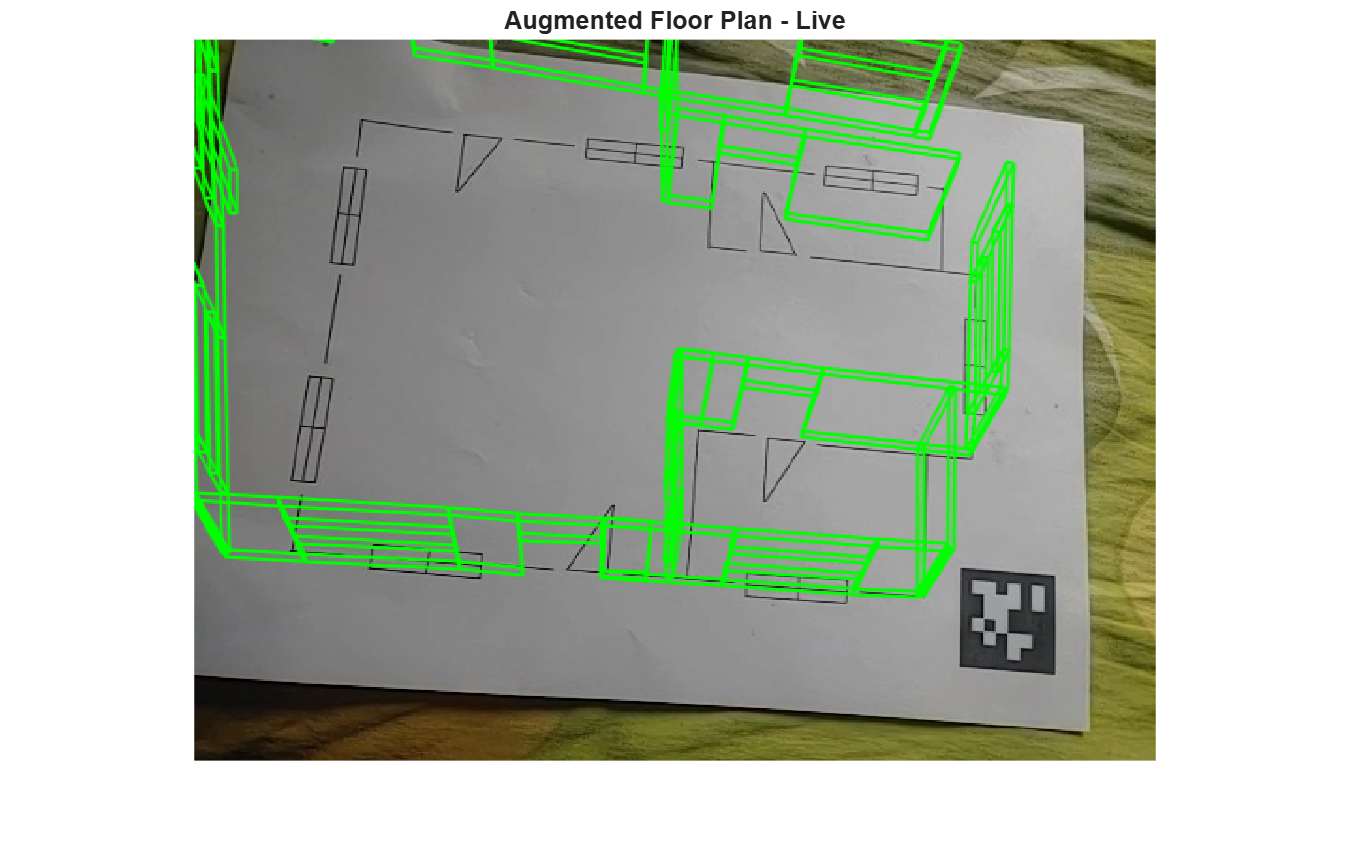

% --- Setup ---
cam = webcam('DroidCam Source');  % Initialize webcam
frameRate = 10;  % Adjust if needed
%tagSize = 43;    % mm
%tagFamily = "tag36h11";

% Load intrinsics (from Camera Calibrator App)
load("calibrationSession.mat");  % should contain 'cameraParams'


% Wall and floor plan properties
wallHeight = 50;      % mm
wallThickness = 2;    % mm

% Assume lines_world already computed from a reference image
% If not, detect lines in one frame and use img2world2d to get lines_world

% Create a figure to display
figure;

% Main loop
while true
    % --- Capture frame from webcam ---
    I = snapshot(cam);

    % --- Detect AprilTag and get pose ---
    try
        [~, ~, tagPose] = readAprilTag(I, tagFamily, intrinsics, tagSize);

        % Rotate Z axis if needed
        rotationAngles = [0 180 0];
        tform = rigidtform3d(rotationAngles, [0 0 0]);
        updatedR = tagPose.R * tform.R;
        tagPose = rigidtform3d(updatedR, tagPose.Translation);
    catch
        warning('Tag not found in this frame. Skipping...');
        imshow(I);
        title('No AprilTag Detected');
        pause(1/frameRate);
        continue;
    end

    % --- Project floor plan into image ---
    augmentedImage = projectExtrudedPlan(I, wall_lines_world, door_markers_world, window_markers_world, intrinsics, tagPose, wallHeight, wallThickness);

    % --- Display ---
    imshow(augmentedImage);
    title('Augmented Floor Plan - Live');
    drawnow;
    pause(1 / frameRate);  % Maintain real-time pace
end